FSK transmission.

The first step is to load the bits to transmitt on the given channel.

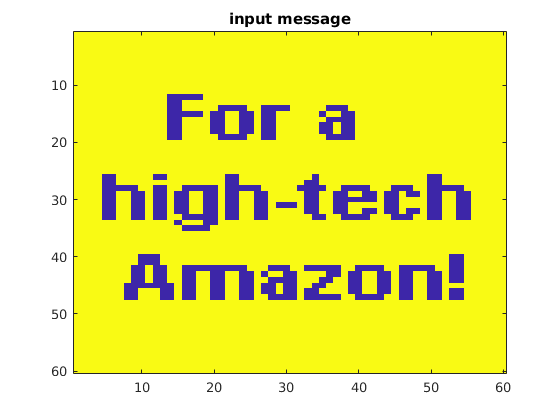

inputImage=load('/home/rodrigo/Documentos/documendos_ssd/documentos mestrado/matérias/digital_transmission/digital_transmission_git/fsk_trans/image.txt');  %load image from file
txBitstream=inputImage(:);%convert matrix to a column vector
imagesc(inputImage); title('input message');

Now we will define the constraints of the transmission, like sampling frequency, the basis functions, and the channel parameters.

f0 = 980;   %freq. of bit 0
f1 = 1180;   %freq. of bit 1
fsymbol = 300; %100;  %symbol frequency, the rate is R = 1/fsymbol(in symbols/sec or bauds)
Fs = 44.1*1e3; %8000;   %sampling frequency in Hz
set_vendor_parameters(Fs,fsymbol,f1,f0);
vendor_params = get_vendor_parameters;

Modulation

y_total = your_transmiter(txBitstream);

    "SNR : "    "4.9916"

    "SNR : "    "6.9824"

    "Power of s - wgn (dBm) : "    "-51.6732"

    "Power of s (dBm) : "    "-50.4934"



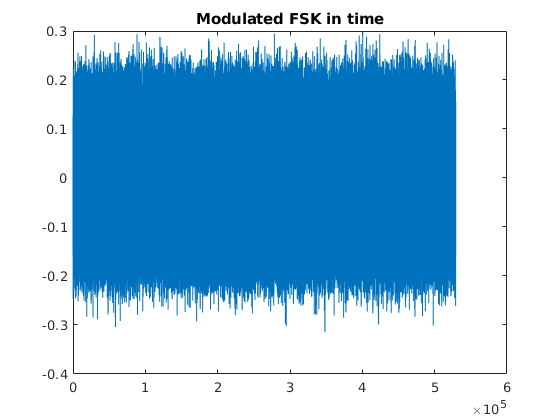

plot(y_total(:)');
%plot(x_total_in_time);
title(['Modulated FSK in time']);

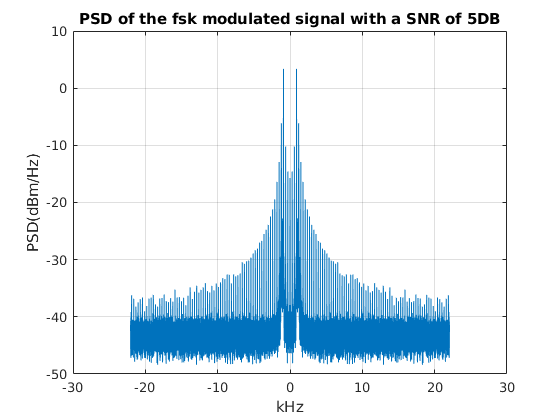

[psdIndB,f]=ak_psd(y_total(:)',Fs);
%[psdIndB,f]=ak_psd(x_total_in_time,Fs);
plot(f/1e3,psdIndB);
title(['PSD of the fsk modulated signal with a SNR of 5DB']);
xlabel('kHz') ;
ylabel('PSD(dBm/Hz)');
grid on;

Demodulate the FSK signal to bits

[rxBitstream,receivedCoefficients] = your_receiver(y_total);

Results

%%%%%%%%%%%%%%%%%%%
%Evaluation
%%%%%%%%%%%%%%%%%%%
%count number of de errors:
numErrors = sum(abs(txBitstream- rxBitstream));
BER = 100 * numErrors / length(txBitstream);
disp(['BER = ' num2str(BER) ' %']);

BER = 0 %


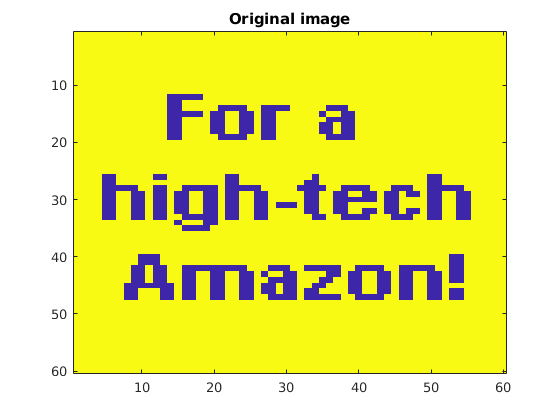

%show the images
imagesc(inputImage); title('Original image'); %show image

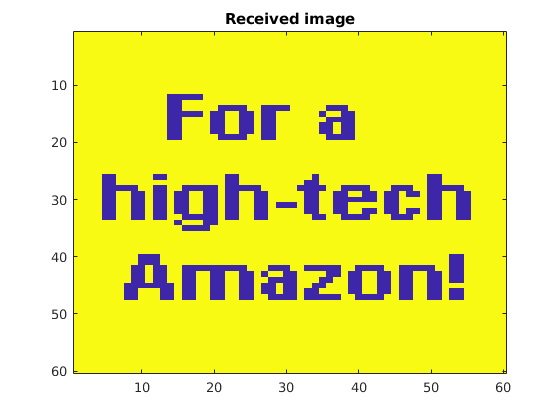

[Nrow, Ncolumns] = size(inputImage);
receivedImage=reshape(rxBitstream,Nrow, Ncolumns);
imagesc(receivedImage); title('Received image');

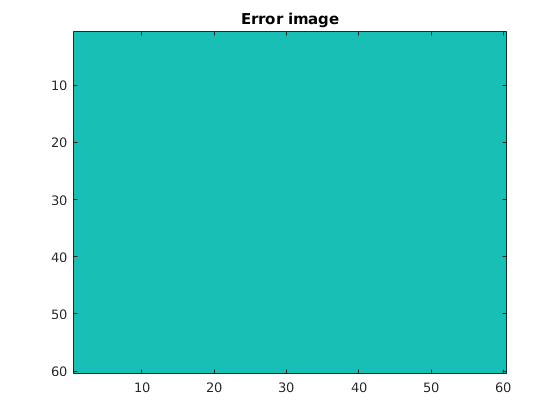

imagesc(inputImage - receivedImage); title('Error image');

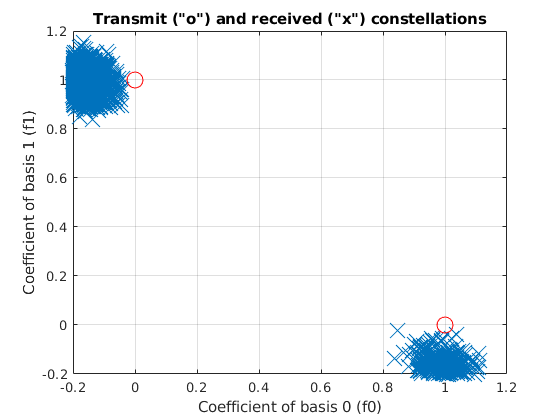

%show the constellations
% new_rx = rxBitstream_to_symbols(rxBitstream);
new_rx = receivedCoefficients;
plot(new_rx(1,:),new_rx(2,:),'x',...
    'MarkerSize',16); hold on
plot(vendor_params.X0(1),vendor_params.X0(2),'or','MarkerSize',12); 
plot(vendor_params.X1(1),vendor_params.X1(2),'or','MarkerSize',12);
title('Transmit ("o") and received ("x") constellations');
xlabel('Coefficient of basis 0 (f0)');
ylabel('Coefficient of basis 1 (f1)');
grid
axis([-0.2 1.2 -0.2 1.2])

Functions

function sn = SNR_c(x,v)
    P_x = 1*(sum(x.^2)) /length(x);
    P_v = 1*(sum(v.^2)) /length(v);
    sn = 10*log10(P_x/P_v);
end

function db = power_db(x)
    P_x = 1*(sum(x.^2)) /length(x);
    db = 10*log10(P_x/1*0.001);
end

function set_vendor_parameters(Fs,fsymbol,f0,f1)
    global vendor_params
    vendor_params.title = 'Vendor parameters';
    vendor_params.f0 = f0;
    vendor_params.f1 = f1;
    vendor_params.Fs = Fs;
    vendor_params.fsymbol = fsymbol;
    vendor_params.T_symbolDuration = 1/fsymbol;
    T_sample = 1/Fs; %sampling period in seconds
    t = 0:T_sample:vendor_params.T_symbolDuration-T_sample; %discrete-time for one symbol
    %create the waveform for each basis function
    vendor_params.basis0 = cos(2*pi*f0*t);
    vendor_params.basis1 = cos(2*pi*f1*t);
    %normalize the basis functions by the norm to obtain unity energy
    vendor_params.basis0 = vendor_params.basis0 / sqrt(sum(vendor_params.basis0.^2));
    vendor_params.basis1 = vendor_params.basis1 / sqrt(sum(vendor_params.basis1.^2));
    %organize bases as columns of a matrix
    vendor_params.A=[transpose(vendor_params.basis0) transpose(vendor_params.basis1)];
    vendor_params.N_samplesPerSymbol = length(vendor_params.basis0); %number of samples per symbol, also
    %known as "oversampling" factor
    %create the symbol constellation with 2 symbols
    vendor_params.X0 = [1; 0];
    vendor_params.X1 = [0; 1];
end

function r = get_vendor_parameters
    global vendor_params
    r = vendor_params;
end

function s = your_transmiter(txBitstream)
    %%%%%%%%%%%%%%%%%%%
    %Modulate to transmit
    %%%%%%%%%%%%%%%%%%%
    vendor_params = get_vendor_parameters;
    N_symbols = length(txBitstream); %number of symbols (or bits, because binary)
    %pre-allocate space for all message duration:
    x_total=zeros(vendor_params.N_samplesPerSymbol, N_symbols);
    for i=1:N_symbols  %i is the i-th symbol
        if txBitstream(i)==1
            X=vendor_params.X1; %transmit the symbol corresponding to bit 1
        else
            X=vendor_params.X0; %transmit the symbol corresponding to bit 0
        end
        x_total(:,i) = vendor_params.A*X; %modulate via block transform
    end
    x_total_in_time = x_total(:)';
    randn('seed',319); % set random seed
    P_x = 1*(sum(x_total_in_time.^2)) /length(x_total_in_time);
    wgn = randn(size(x_total)); %Gaussian noise
    wgn_factor = sqrt(P_x/sqrt(10));% -0.0233
    wgn = wgn_factor*wgn;
    s = x_total + wgn; %add Gaussian noise
    disp(["SNR : ", num2str(SNR_c(x_total_in_time,wgn(:)'))]);
    disp(["SNR : ", num2str(10*log10(snr(x_total_in_time,wgn(:)')))]);
    disp(["Power of s - wgn (dBm) : ", num2str(power_db(x_total_in_time))]);
    disp(["Power of s (dBm) : ", num2str(power_db(s(:)'))]);
    
end

function [s,v] = your_receiver(r)
    %%%%%%%%%%%%%%%%%%%
    %Initialize receiver (demodulator)
    %%%%%%%%%%%%%%%%%%%
    vendor_params = get_vendor_parameters;
    Ah = vendor_params.A'; %assume that A is unitary and the inverse is the Hermitian
    %%%%%%%%%%%%%%%%%%%
    %Demodulate the received signal
    %%%%%%%%%%%%%%%%%%%
    %Note that we assume the basis functions were created in the receiver
    %with perfect synchronism to the transmitter. Hence, it is an ideal
    %"synchronous" reception.
    size_r = size(r);
    N_symbols = size_r(2);
    outputBits = zeros(N_symbols,1); %pre-allocate space
    receivedCoefficients = zeros(2,N_symbols); %pre-allocate space
    %reorganize y_total as a matrix for simplicity
    r=reshape(r, vendor_params.N_samplesPerSymbol, N_symbols);
    for i=1:N_symbols  %i is the i-th symbol
        x=r(:,i);
        %demodulate via block transform ("correlative decoding")
        X = Ah * x; %calculate the inner product with each basis function
        receivedCoefficients(:,i) = X;
        %find the constellation point nearest to the coefficients X:
        distanceToSymbol0 = sqrt(sum( (X-vendor_params.X0).^2 ));
        distanceToSymbol1 = sqrt(sum( (X-vendor_params.X1).^2 ));
        if distanceToSymbol0 < distanceToSymbol1
            outputBits(i) = 0; %symbol 0 is the closest one
        else
            outputBits(i) = 1; %symbol 1 is the closest one
        end
    end
    
    s = outputBits;
    v = receivedCoefficients;
end

function sv = rxBitstream_to_symbols(r)
    size_r = size(r);
    N_symbols = size_r(1);
    r = r';
    sv = zeros(2,N_symbols);
    for i=1:N_symbols  %i is the i-th symbol
        bit_i =r(i);
        if bit_i == 1
            bit_j = 0; %symbol 0 is the closest one
        else
            bit_j = 1; %symbol 1 is the closest one
        end
        sv(:,i) = [bit_i; bit_j];
    end
end